%Ex1

clear variables
n = 0 : 5;
u = @(n) (n>=0);
x = @(n) u(n) - u(n-2);
y = @(n) (0.2.^n).*u(n);
sx = 0; ex = 5; dtx = sx : ex;
sy = 0; ey = 5; dty = sy : ey;
dtw = sx + sy : ex + ey;
subplot(3,1,1);stem(dtx,x(dtx))
subplot(3,1,2);stem(dty,y(dty))
w = conv(x(dtx),y(dty))

w =     1.0000    1.2000    0.2400    0.0480    0.0096    0.0019    0.0003         0         0         0         0


subplot(3,1,3);stem(dtw,w);hold;

Current plot held


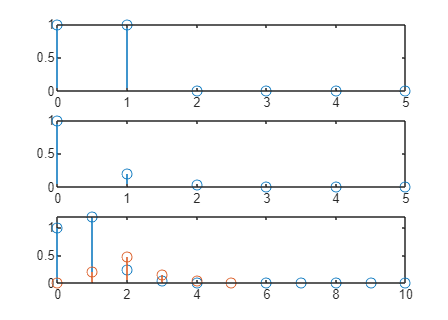

stem(n, (1-5.^(-n))/4 .* (u(n)-u(n-2)) + 6.*n.*u(n-2).*(1/5).^n);